## Программа расчета эффективности планарно-волноводных антен

### Установка первоначальных данных

Излучатель

Opt_ource(1).P = 0.10; % Мощность излучения в Вт
Opt_ource(1).lambda_max = 365; % Максимум излучения нм
Opt_ource(1).lambda_FWHM = 10; % Полуширина линии нм

N_ph = 10;

#### Характеристики ПВА

Материал ПВА

% ПММА
PFA.n = 1.52;


Характеристики люминофора

% Пока без характеристик
Lum_ = NaN;

Характеристики выводной части (приемника)

d_f = 10;

Характеристики границы

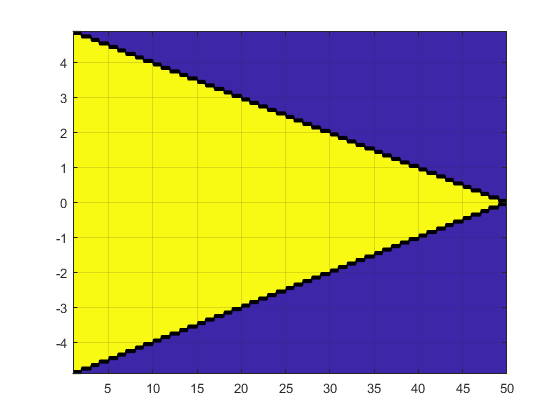

% Формируем координаты расчета
x = 1:0.1:100;
clear gran_a
global gran_a;
gran_a = [d_f / 2, -0.1];

x = x (is_PFA(x,0));
y = -max(forma_gran_L(x).*is_PFA(x,0)):0.1:max(forma_gran_L(x).*is_PFA(x,0));


[X,Y] = meshgrid(x,y);
M = is_PFA(X,Y);
figure
contourf(X,Y,M)
grid on

### Расчет

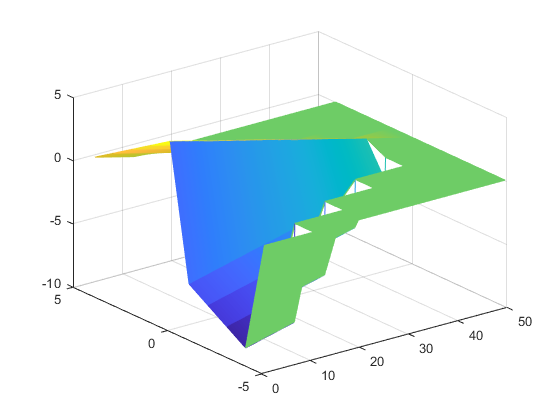

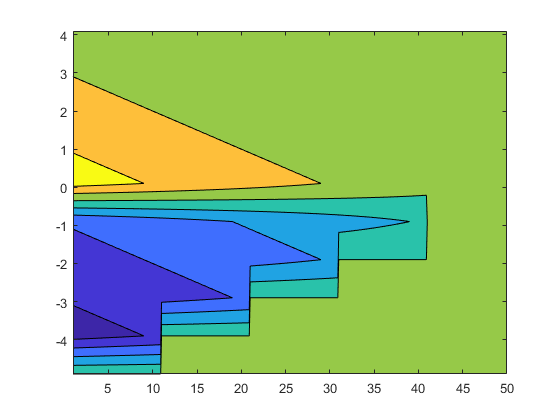

for kx = 1:size(X,1)
    for ky = 1:size(X,2)
        if is_PFA(X(kx,ky), Y(kx,ky))
               
        end
    end
end

figure
mesh(X,Y,M)

function result = forma_gran(x)
%% Форма границы (полином)
global gran_a
result = 0;
for i = 1:numel(gran_a)
    result = result + gran_a(i) .* x .^ (i-1);
end
end

function result = forma_gran_L(x)
%% Форма левой границы
result = forma_gran(x);
end
function result = forma_gran_R(x)
%% Форма правой границы
result = -forma_gran(x);
end




function result = is_PFA(x, y)
result = and (y >= forma_gran_R(x), y <= forma_gran_L(x));
end